clc
clear

imgPath = 'landscape.jpg';


## Image preprocessing

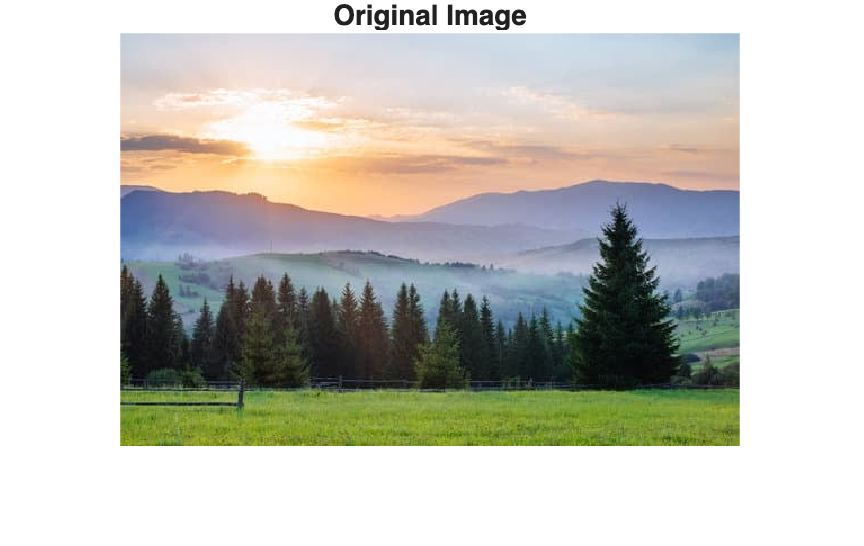

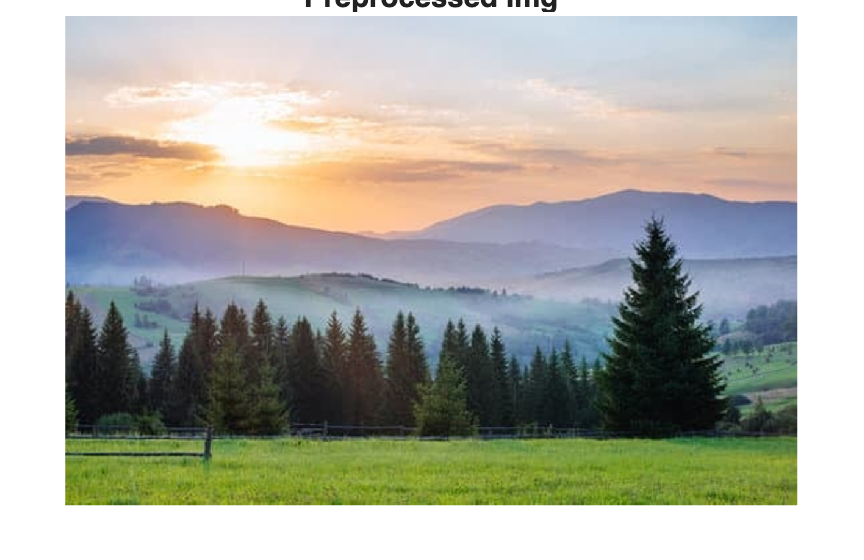

minW = 600;        % Min input width (px)
maxW = 3000;       % Max input width (px)
Wout = 1200;       % Output width (px)

img = im2double(imread(imgPath));
processedImg = preprocessImage(img, minW, maxW, Wout);

Ilab = rgb2lab(processedImg);


## Color palette generation & palette optimization

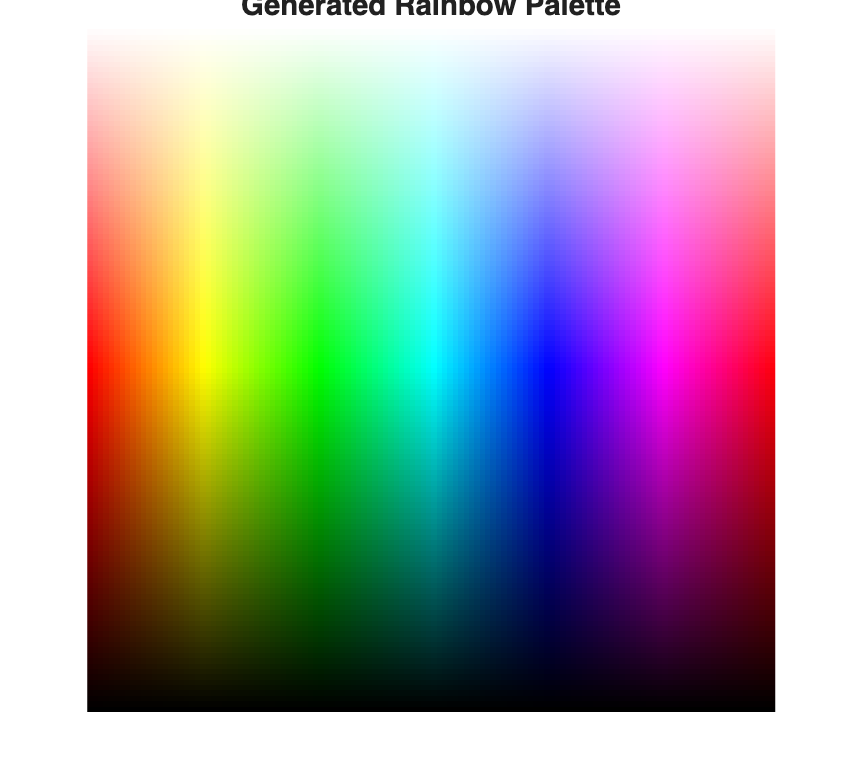

numColors= 128;              % Number of base colors
numShades = 128;             % Number of shades of the base colors

sampleQuantity = 50000;      % Number of samples for the optimized palette
numOptimizedBeads = 500;     % Number of colors in the optimized palette

[fullPaletteLab, paletteImage] = make_rainbow_palette(numColors, numShades);

figure;
imshow(imresize(paletteImage, 20, 'nearest')); 
title('Generated Rainbow Palette');

fprintf('Generated Palette (%d colors)', numColors * numShades)

Generated Palette (16384 colors)

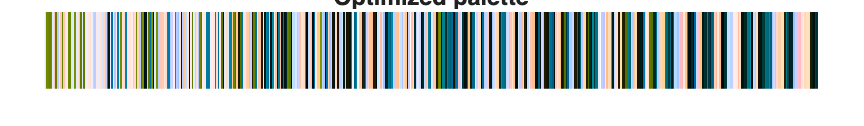


[optimizedPaletteLab, optPaletteSwatch] = optimize_palette(Ilab, fullPaletteLab, numOptimizedBeads, sampleQuantity);

figure;
imshow(imresize(optPaletteSwatch, 15, "nearest"));
title("Optimized palette");

fprintf('Optimized Palette (%d colors chosen from %d)', numOptimizedBeads, numColors * numShades)

Optimized Palette (500 colors chosen from 16384)

## Image reconstruction

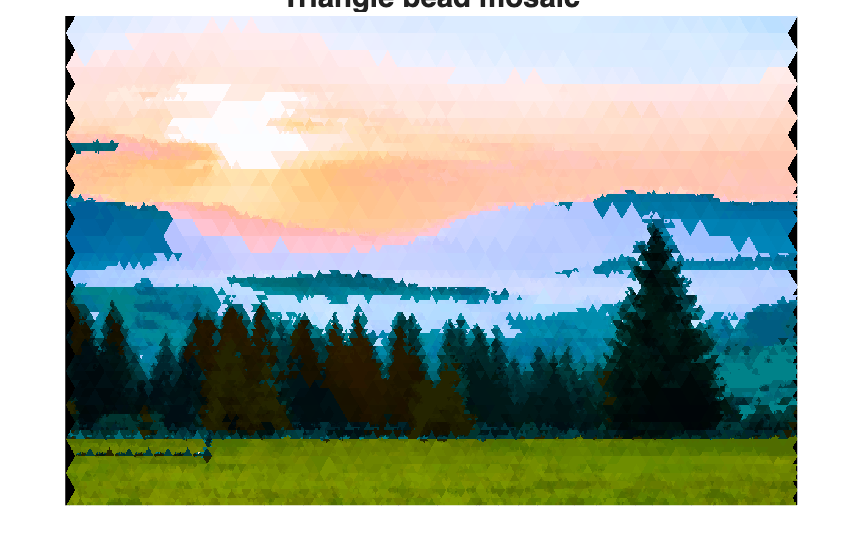

maxSize = 32;              % Largest triangle size (px)
minSize = 2;               % Smallest triangle size (px)
detailThreshold = 10;      % How much brightness variation triggers a split

[mosaicRGB, idxMap] = reproduce_adaptive_triangle(Ilab, optimizedPaletteLab, maxSize, minSize, detailThreshold);

figure;
imshow(mosaicRGB);
axis image off;
title('Triangle bead mosaic');

fprintf("Largest triangles: %d and smallest triangles: %d", maxSize, minSize)

Largest triangles: 32 and smallest triangles: 2

## Evaluation

% TODO: Implement evaluation based on SSIM, SCIELAB